Estimation of a noise model of type Box-Jenkins with Contsid. 

Using Matlab's procest seems preferable and produces the desired results in terms of residual analysis.

clear;
stepStruct = load("Simulated_stepdata.mat");
trainingStruct = load("Simulated_data1.mat");
validationStruct = load("Simulated_data2.mat");
Ts = trainingStruct.Ts;
dataStep = iddata(stepStruct.y, stepStruct.u, Ts, 'InterSample', 'zoh');
dataEst= iddata(trainingStruct.y, trainingStruct.u, Ts, 'Intersample', 'zoh');
dataVal = iddata(validationStruct.y, validationStruct.u, Ts, 'Intersample', 'zoh');
% free params sys nom.
nb=1;
% free params noise nom.
nc=1;
% free params noise denom. (order one higher than free params)
nd=1;
% free params sys denom. (order one higher than free params)
nf=1;
% delay in sampling times
nk=23;
    
% estimation
[Mrivc,Ce,De] = rivc(dataEst,[nb nc nd nf nk]);
present(Mrivc)

                                                                                                                    
Mrivc =                                                                                                             
Continuous-time OE model: y(t) = [B(s)/F(s)]u(t)                                                                    
  B(s) = 0.5322 (+/- 0.01313)                                                                                       
                                                                                                                    
  F(s) = s + 0.7754 (+/- 0.02647)                                                                                   
                                                                                                                    
Input delays (listed by channel): 0.23                                                                              
Parameterization:                                               

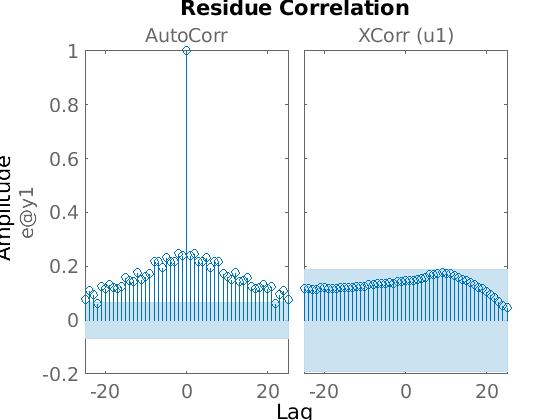

% Noise information doesn't seem integrated into the model, so the residual
% analysis is disappointing
resid(dataEst, Mrivc);

% ARMA model
noiseFilter_d = tf(Ce,De,Ts)

noiseFilter_d =
 
  z - 0.8522
  ----------
  z - 0.9665
 
Sample time: 0.01 seconds
Discrete-time transfer function.



noiseFilter_c = d2c(noiseFilter_d, 'tustin')

noiseFilter_c =
 
  0.9419 s + 15.03
  ----------------
     s + 3.406
 
Continuous-time transfer function.



% similar to the additive ARMA model we get when using procest with 'ARMA1'
% options